# Permutation List of Pairs of Receiver and Transmitter on Map

## Overview :

This example to determine the location of receiver and transmitter on the "actual/real" map and later compute the permutation list of pairs of receiver and transmitter.

**What is Permutation? **

A **permutation** is a mathematical technique that determines the number of possible arrangements in a set when the order of the arrangements matters. (Wikipedia)

## Product Focus :

- MATLAB

- Mapping Toolbox

## Contents

## 1.0 Tips to display map in MATLAB

Overview : [https://www.mathworks.com/help/map/map-display.html](https://www.mathworks.com/help/map/map-display.html) 

Basically, there are two function to display map using Mapping Toolbox:

(1) geoshow : [https://www.mathworks.com/help/map/ref/geoshow.html?s_tid=doc_ta](https://www.mathworks.com/help/map/ref/geoshow.html?s_tid=doc_ta)

(2) mapshow : [https://www.mathworks.com/help/map/ref/mapshow.html](https://www.mathworks.com/help/map/ref/mapshow.html) 

## 2.0 Read GeoTif - Singapore

Download geo_tif from [Urban Land Cover, Singapore, Singapore, 2000 in EarthWorks (stanford.edu)](https://earthworks.stanford.edu/catalog/stanford-xk900hn2991)

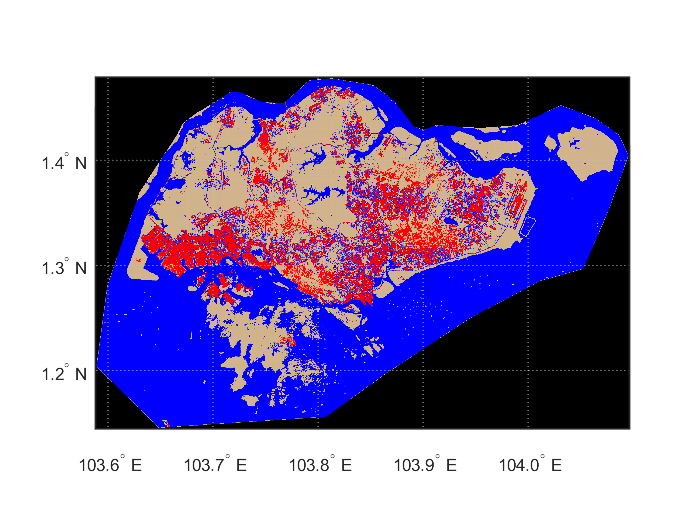

[A,R,cmap] = readgeoraster('stanford-sp911xf4686-geotiff.tif','CoordinateSystemType',"geographic","OutputType","uint8");
latlim = R.LatitudeLimits;
lonlim = R.LongitudeLimits;
usamap(latlim,lonlim)
%info1 = georasterinfo('stanford-sp911xf4686-geotiff.tif');
geoshow(A,R)

## 2.1 Zoom bigger to latitude(1.3-1.4) and longitude(103.7-103.8)

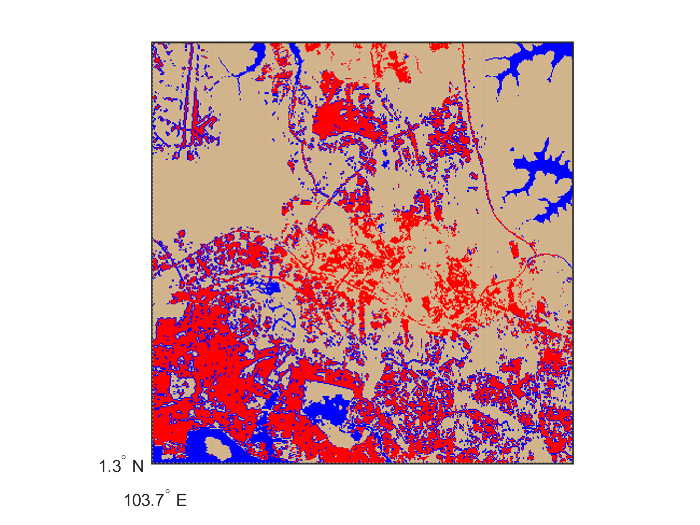

latlim = [1.3 1.4];
lonlim = [103.7 103.8];
usamap(latlim,lonlim)
geoshow(A,R)

## 3.0 Plot Area - Potential Location of transmitter and receiver

In the previous section, you may open it as figure. 

In the figure, you may use triangle to draw the potential area for transmitter and receiver.

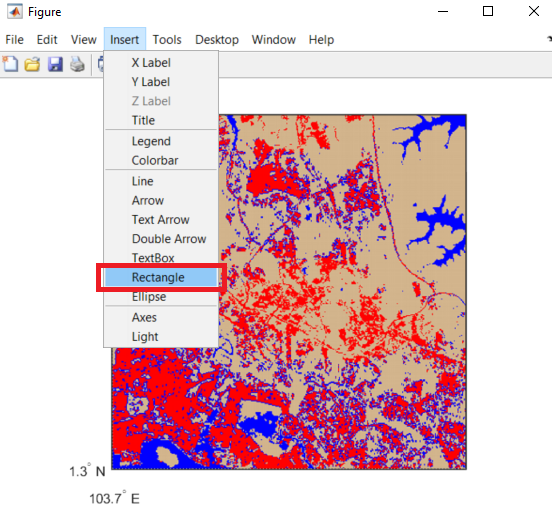

After drawing the rectagle, you may generate the code as below:

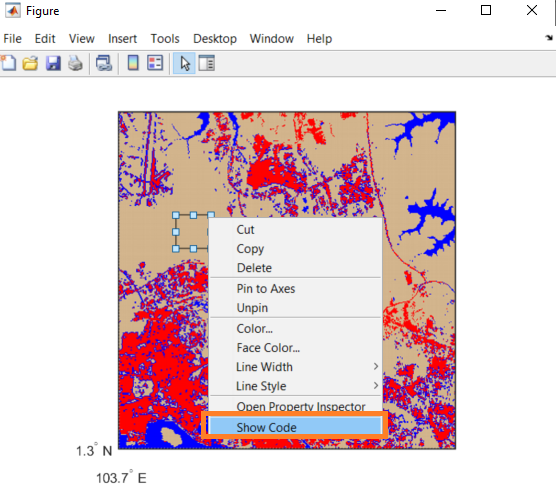

In the code, please copy the coordinate and use defined function - coverttolatlon (At the end of this script) to convert the points to the accepted longitude and latitude points for geoshow to display polygon.

Besides the approach above, you may direct assign the latitude and longtitude to geoshow to display the polygon.

In example below, we direct assign the latitude and longitude to draw the potential area for transmitter and use the relative location in the figure (1st approach) to draw the potential area for receiver.

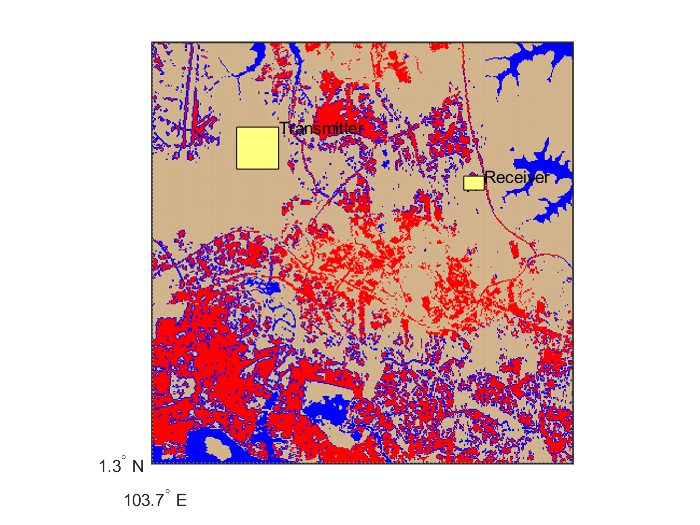

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
point = [0.64975 0.741293532338309 0.0335833333333332 0.048922056384743]
[lat2,lon2]=coverttolatlon(point,latlim,longlim);
usamap([1.3 1.4],[103.7 103.8])
geoshow(A,R)
hold on
geoshow(lat1,lon1,'DisplayType', 'polygon');
textm(max(lat1), max(lon1),'Transmitter')
geoshow(lat2,lon2,'DisplayType', 'polygon');
textm(max(lat2), max(lon2),'Receiver')
hold off

## 4.0 Draw the line to connect both Centroid

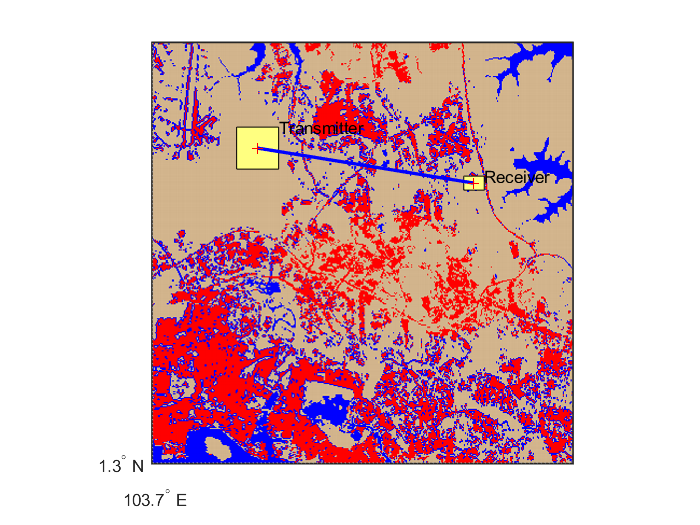

polyin1 = polyshape(lon1,lat1);
[x1,y1] = centroid(polyin1);

polyin2 = polyshape(lon2,lat2);
[x2,y2] = centroid(polyin2);

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
% [0.64975 0.741293532338309 0.0335833333333332 0.048922056384743]
[lat2,lon2]=coverttolatlon(point,latlim,longlim);
usamap([1.3 1.4],[103.7 103.8])
geoshow(A,R)
hold on
geoshow(lat1,lon1,'DisplayType', 'polygon');
textm(max(lat1), max(lon1),'Transmitter')
geoshow(lat2,lon2,'DisplayType', 'polygon');
textm(max(lat2), max(lon2),'Receiver')
geoshow([y1 y2] ,[x1 x2] ,'DisplayType', 'line',"LineWidth",2);
geoshow(y1 ,x1 ,'DisplayType', 'point');
geoshow(y2 ,x2 ,'DisplayType', 'point');
hold off

## 5.0 Find the coordinate points along the line 

- It is not relevant to the example

- It demonstrates how to find the coordinates (x,y) along line

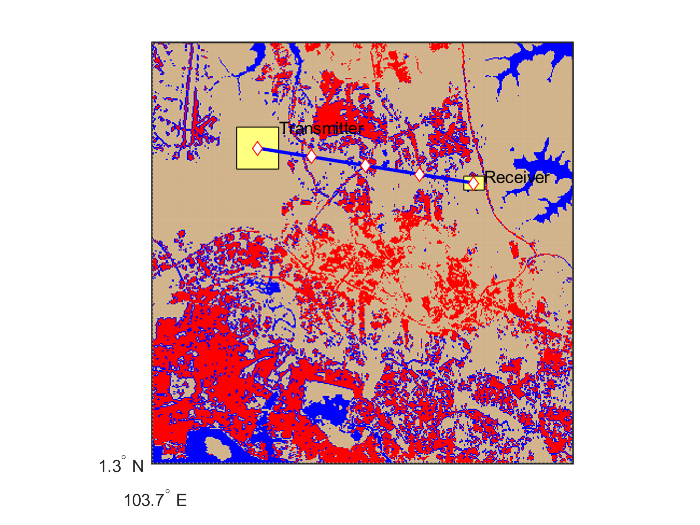

p = polyfit([x1 x2],[y1 y2],1);
x_long = linspace(x1,x2,5);
y_lat = polyval(p,x_long);

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
% [0.64975 0.741293532338309 0.0335833333333332 0.048922056384743]
[lat2,lon2]=coverttolatlon(point,latlim,longlim);
usamap([1.3 1.4],[103.7 103.8])
geoshow(A,R)
hold on
geoshow(lat1,lon1,'DisplayType', 'polygon');
textm(max(lat1), max(lon1),'Transmitter')
geoshow(lat2,lon2,'DisplayType', 'polygon');
textm(max(lat2), max(lon2),'Receiver')
geoshow([y1 y2] ,[x1 x2] ,'DisplayType', 'line',"LineWidth",2);
geoshow(y1 ,x1 ,'DisplayType', 'point');
geoshow(y2 ,x2 ,'DisplayType', 'point');
geoshow(y_lat,x_long,'DisplayType','multipoint','Marker',"diamond",'Color','m','MarkerFaceColor',"auto");
hold off

## 6.0 Zoom into Receiver location - get all possible coordinates with equally space inside the area

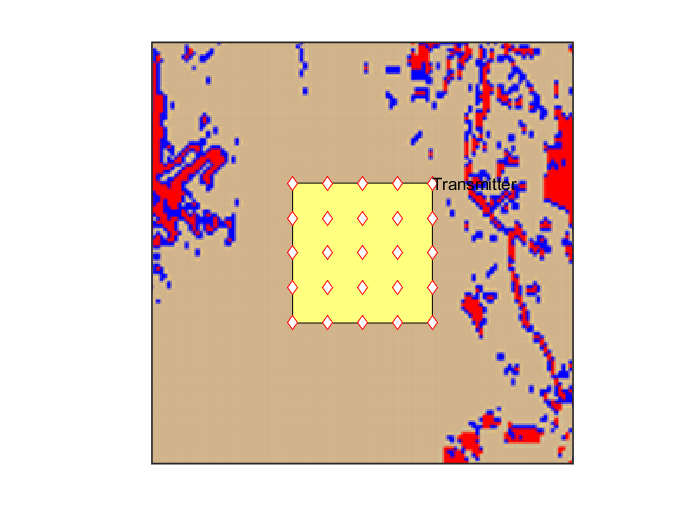

longitude_x = linspace(103.72,103.73,5);
longitude_x = repmat(longitude_x,[5 1]);
longitude_x = reshape(longitude_x,[],1);
latitude_y = linspace(1.37,1.38,5);
latitude_y = repmat(latitude_y',[1 5]);
latitude_y  = reshape(latitude_y,[],1);

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
usamap([1.36 1.39],[103.71 103.74])
geoshow(A,R)
hold on
geoshow(lat1,lon1,'DisplayType', 'polygon');
textm(max(lat1), max(lon1),'Transmitter')
geoshow(latitude_y(:,1),longitude_x(:,1),'DisplayType','multipoint','Marker',"diamond",'Color','m','MarkerFaceColor',"auto");
hold off

## 7.0 Zoom into Receiver location - Get All possible coordinate for Receiver with equally space for boundary

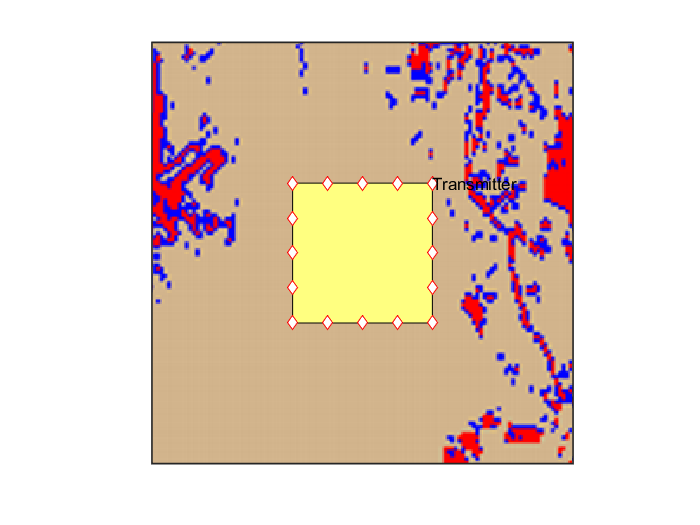

longitude_x = linspace(103.72,103.73,5);
longitude_x = repmat(longitude_x,[5 1]);
longitude_x = reshape(longitude_x,[],1);
latitude_y = linspace(1.37,1.38,5);
latitude_y = repmat(latitude_y',[1 5]);
latitude_y  = reshape(latitude_y,[],1);

k = boundary(longitude_x,latitude_y);

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
usamap([1.36 1.39],[103.71 103.74])
geoshow(A,R)
hold on
geoshow(lat1,lon1,'DisplayType', 'polygon');
textm(max(lat1), max(lon1),'Transmitter')
geoshow(latitude_y(k),longitude_x(k),'DisplayType','multipoint','Marker',"diamond",'Color','m','MarkerFaceColor',"auto");
hold off

## 8.0 Break Area into 4 Equal Size Areas

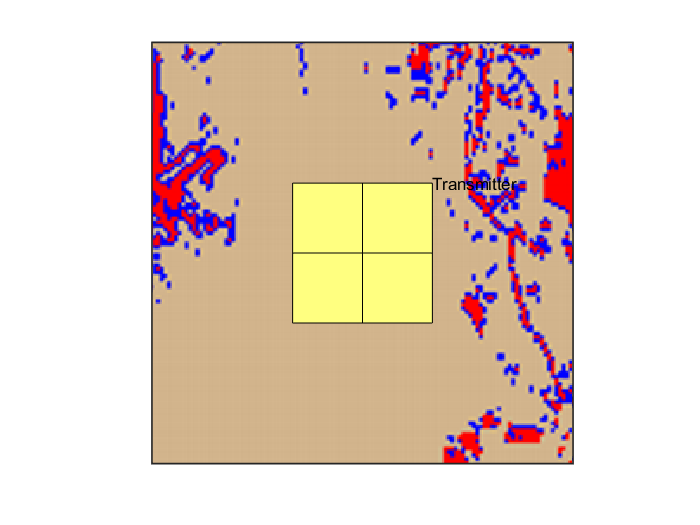

longitude_x = linspace(103.72,103.73,3);
longitude_x = repmat(longitude_x,[3 1]);
latitude_y = linspace(1.37,1.38,3);
latitude_y = repmat(latitude_y',[1 3]);

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
usamap([1.36 1.39],[103.71 103.74])
geoshow(A,R)
hold on
plot(longitude_x,latitude_y,'k')
textm(max(lat1), max(lon1),'Transmitter')
plotsmallerarea(latitude_y,longitude_x)
hold off

## 9.0 Permutate to get all the possible pairs of transmitter and receiver

Get All possible coordinate for transmitter and receiver

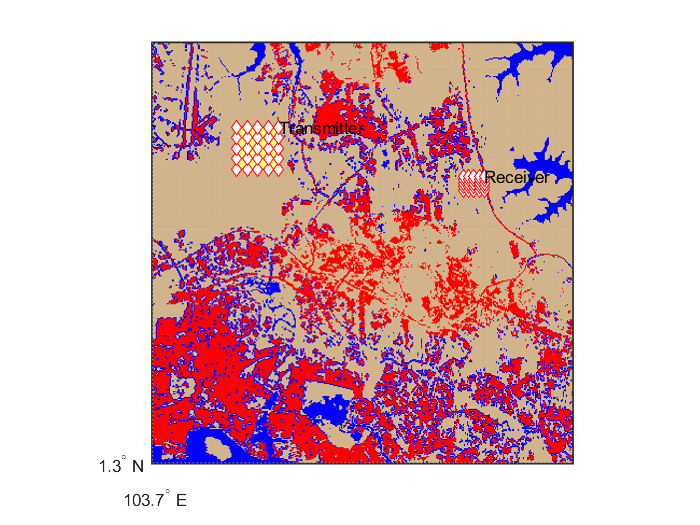

figure
lon1 = [103.72 103.72 103.73 103.73 103.72]';
lat1 = [1.37 1.38 1.38 1.37 1.37]';
% [0.64975 0.741293532338309 0.0335833333333332 0.048922056384743]
[lat2,lon2]=coverttolatlon(point,latlim,longlim);

longitude_x_transmitter = linspace(103.72,103.73,5);
longitude_x_transmitter = repmat(longitude_x_transmitter,[5 1]);
longitude_x_transmitter = reshape(longitude_x_transmitter,[],1);
latitude_y_transmitter = linspace(1.37,1.38,5);
latitude_y_transmitter = repmat(latitude_y_transmitter',[1 5]);
latitude_y_transmitter  = reshape(latitude_y_transmitter,[],1);

longitude_x_receiver = linspace(min(lon2),max(lon2),5);
longitude_x_receiver = repmat(longitude_x_receiver,[5 1]);
longitude_x_receiver = reshape(longitude_x_receiver,[],1);
latitude_y_receiver = linspace(min(lat2),max(lat2),5);
latitude_y_receiver = repmat(latitude_y_receiver',[1 5]);
latitude_y_receiver  = reshape(latitude_y_receiver,[],1);

usamap([1.3 1.4],[103.7 103.8])
geoshow(A,R)
hold on
geoshow(lat1,lon1,'DisplayType', 'polygon');
textm(max(lat1), max(lon1),'Transmitter')
geoshow(lat2,lon2,'DisplayType', 'polygon');
textm(max(lat2), max(lon2),'Receiver')
geoshow(latitude_y_receiver,longitude_x_receiver,'DisplayType','multipoint','Marker',"diamond",'Color','m','MarkerFaceColor',"auto");
geoshow(latitude_y_transmitter,longitude_x_transmitter,'DisplayType','multipoint','Marker',"diamond",'Color','m','MarkerFaceColor',"auto");
hold off

index_receiver = 1:1:length(latitude_y_receiver);
index_transmitter = 1:1:length(latitude_y_transmitter);
[m,n] = ndgrid(index_receiver ,index_transmitter);
m = m(:);
n = n(:);
Z = table(longitude_x_receiver(m),latitude_y_receiver(m),longitude_x_transmitter(n),latitude_y_transmitter(n),'VariableNames', {'Receiver Longitude','Receiver Latitude','Transmitter Longitude','Transmitter latitude'})

Z = 625×4 table
    Receiver Longitude    Receiver Latitude    Transmitter Longitude    Transmitter latitude
    __________________    _________________    _____________________    ____________________

     103.774129353234             1.364975            103.72                    1.37        
     103.774129353234     1.36581458333333            103.72                    1.37        
     103.774129353234     1.36665416666667            103.72                    1.37        
     103.774129353234           1.36749375            103.72                    1.37        
     103.774129353234     1.36833333333333            103.72                    1.37        
     103.775352404643             1.364975            103.72                    1.37        
     103.775352404643     1.36581458333333            103.72                    1.37        
     103.7

## 10.0 Write to the text file

you may export to Wireless InSite for your simulation.

writetable(Z,"output.txt")

## Helper Function

function [lat1,lon1]=coverttolatlon(point,latlim,longlim)

fixlat = point(1)*(latlim(2)-latlim(1)) + latlim(1);
fixlong = point(2)*(longlim(2)-longlim(1)) + longlim(1);
lengthlat = point(3)*(latlim(2)-latlim(1));
lengthlong = point(4)*(longlim(2)-longlim(1));

lon1 = [fixlong fixlong fixlong+lengthlong fixlong+lengthlong fixlong]';
lat1 = [fixlat fixlat+lengthlat fixlat+lengthlat fixlat fixlat]';

% [0.64975 0.741293532338309 0.0335833333333332 0.048922056384743] 
end

function plotsmallerarea(latitude_y,longitude_x)

for i=1:width(longitude_x)-1
    for j=1:height(longitude_x)-1
        lon1 = [longitude_x(i,j) longitude_x(i+1,j) longitude_x(i+1,j+1) longitude_x(i,j+1) longitude_x(i,j)]';
        lat1 = [latitude_y(i,j) latitude_y(i+1,j) latitude_y(i+1,j+1) latitude_y(i,j+1) latitude_y(i,j)]';
        geoshow(lat1,lon1,'DisplayType', 'polygon');
    end
end
end